## divide train set and test set

data = X_pca;
label = y;

ratio = 0.8;
num_train = floor(length(label)*ratio); 
choose = randperm(length(label)); 

train_data  = data(choose(1:num_train), :);
train_label = label(choose(1:num_train));
test_data   = data(choose(num_train+1:end), :);
test_label  = label(choose(num_train+1:end));

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,-4, 2, -4, 2, 10, 1, 1, 0.2);
toc

*
optimization finished, #iter = 72
nu = 0.972973
obj = -8.989415, rho = -1.003511
nSV = 144, nBSV = 144
*
optimization finished, #iter = 71
nu = 0.965986
obj = -8.865407, rho = -1.004013
nSV = 142, nBSV = 142
*
optimization finished, #iter = 71
nu = 0.965986
obj = -8.868264, rho = -1.002764
nSV = 142, nBSV = 142
*
optimization finished, #iter = 71
nu = 0.993007
obj = -8.865820, rho = -0.996749
nSV = 142, nBSV = 142
*
optimization finished, #iter = 71
nu = 0.993007
obj = -8.873504, rho = -0.996487
nSV = 142, nBSV = 142
*
optimization finished, #iter = 71
nu = 1.000000
obj = -8.868496, rho = 0.003009
nSV = 142, nBSV = 142
Total nSV = 287
*
optimization finished, #iter = 72
nu = 0.972973
obj = -8.988856, rho = -1.002467
nSV = 144, nBSV = 144
*
optimization finished, #iter = 70
nu = 0.958904
obj = -8.740444, rho = -1.004083
nSV = 140, nBSV = 140
*
optimization finished, #iter = 70
nu = 0.958904
obj = -8.743499, rho = -1.002898
nSV = 140, nBSV = 140
*
optimization finished, #iter = 70
nu =

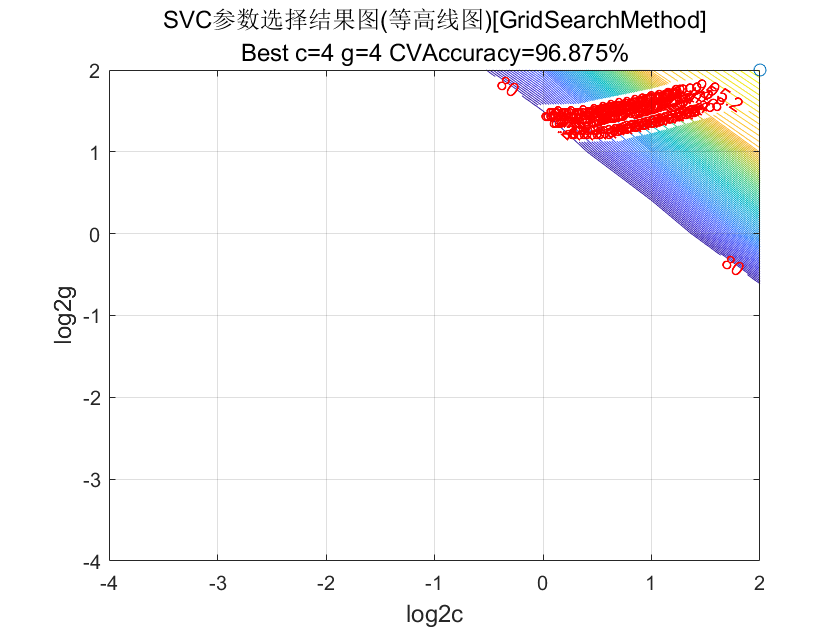

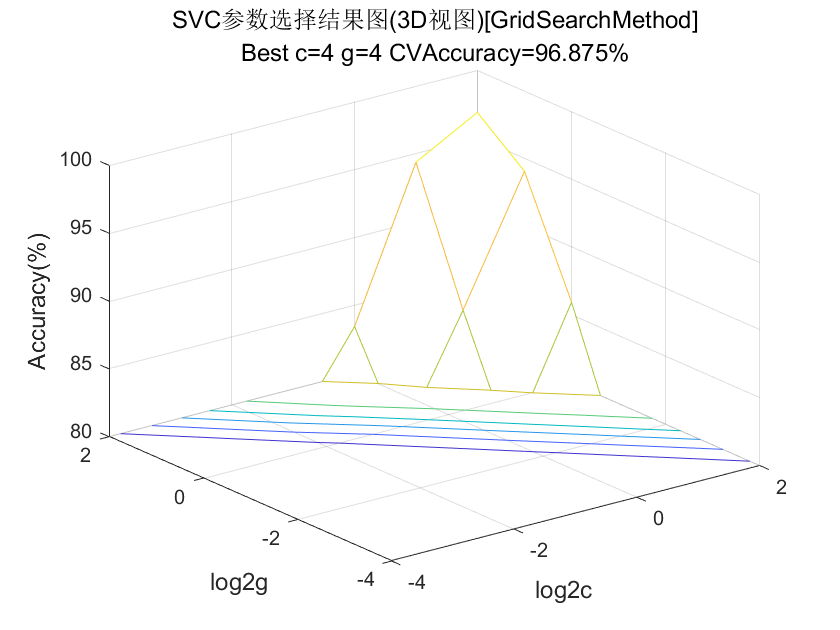

tic
[bestacc, bestc, bestg] = svm_gridsearch(train_label,...
                        train_data,0, 2, 0, 2, 10, 0.1, 0.1, 0.1);

toc

历时 22.350378 秒。


*
optimization finished, #iter = 76
nu = 0.949947
obj = -99.530997, rho = -1.906065
nSV = 142, nBSV = 140
*
optimization finished, #iter = 75
nu = 0.954207
obj = -101.322191, rho = -1.935842
nSV = 142, nBSV = 139
*
optimization finished, #iter = 72
nu = 0.965986
obj = -114.179493, rho = -1.584702
nSV = 143, nBSV = 141
*
optimization finished, #iter = 72
nu = 0.993007
obj = -105.208288, rho = -0.187946
nSV = 142, nBSV = 142
*
optimization finished, #iter = 72
nu = 0.993007
obj = -135.921932, rho = -0.082287
nSV = 142, nBSV = 142
*
optimization finished, #iter = 71
nu = 1.000000
obj = -115.866964, rho = 0.732608
nSV = 142, nBSV = 142
Total nSV = 287
*
optimization finished, #iter = 73
nu = 0.931378
obj = -98.405171, rho = -1.857350
nSV = 138, nBSV = 136
*
optimization finished, #iter = 71
nu = 0.942486
obj = -99.354360, rho = -1.956732
nSV = 138, nBSV = 136
*
optimization finished, #iter = 72
nu = 0.958904
obj = -113.087353, rho = -1.619314
nSV = 141, nBSV = 138
*
optimization finished, 

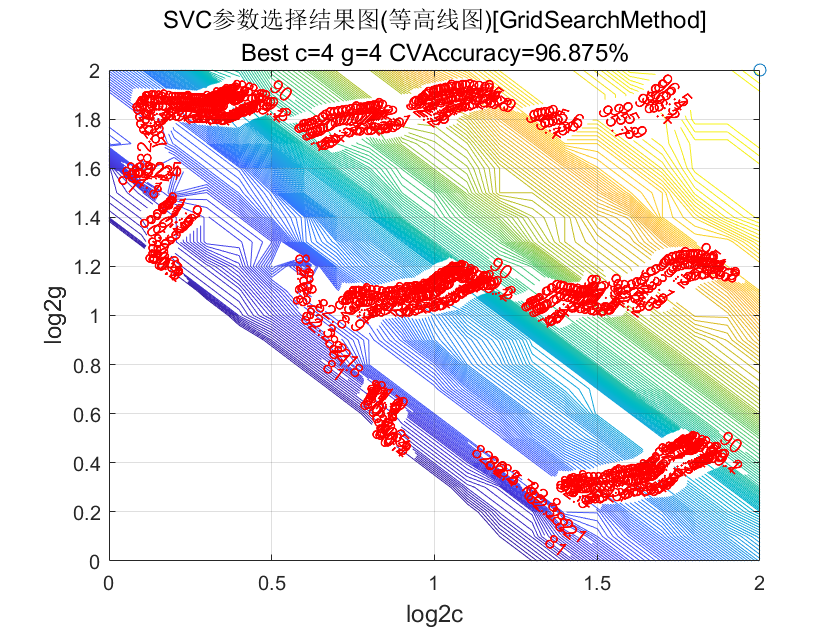

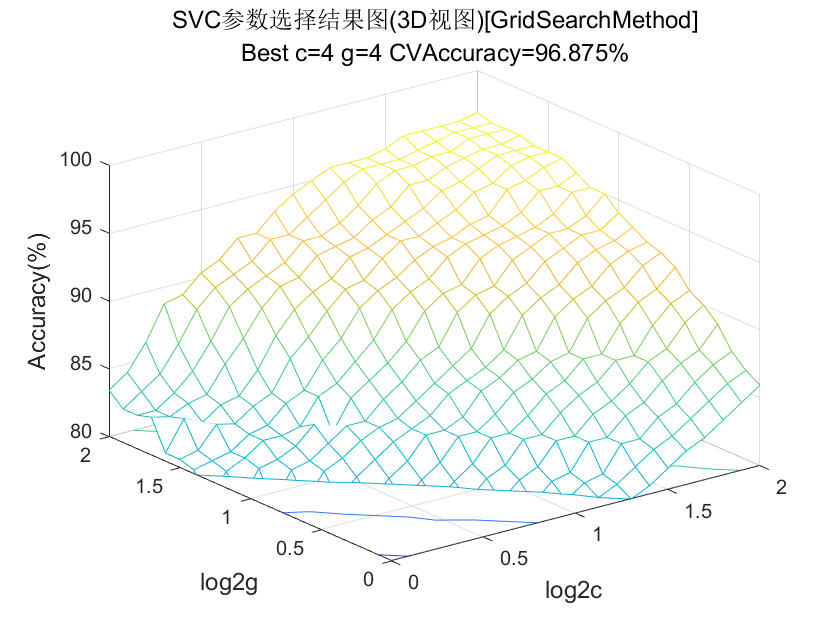

s = 0;
t = 0;
c = bestc;

g = bestg;

历时 157.120642 秒。


options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)]; 
model = libsvmtrain(train_label, train_data, options); 

[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);
[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

*
optimization finished, #iter = 85
nu = 0.719513
obj = -296.678592, rho = 1.973583
nSV = 121, nBSV = 116
*
optimization finished, #iter = 83
nu = 0.746385
obj = -309.674425, rho = 0.340527
nSV = 124, nBSV = 116
*
optimization finished, #iter = 86
nu = 0.860413
obj = -375.437062, rho = 1.707845
nSV = 143, nBSV = 136
*
optimization finished, #iter = 73
nu = 0.789088
obj = -317.980845, rho = -2.052518
nSV = 127, nBSV = 122
*
optimization finished, #iter = 83
nu = 0.985857
obj = -562.070126, rho = -1.494204
nSV = 156, nBSV = 154
*
optimization finished, #iter = 80
nu = 0.903480
obj = -393.306912, rho = 1.457534
nSV = 143, nBSV = 139
Total nSV = 309


Accuracy = 82.5% (264/320) (classification)


Accuracy = 80% (64/80) (classification)
